close all;
% clear;

numPoints = 1000;
turnFraction =0.001

turnFraction = 1.0000e-03

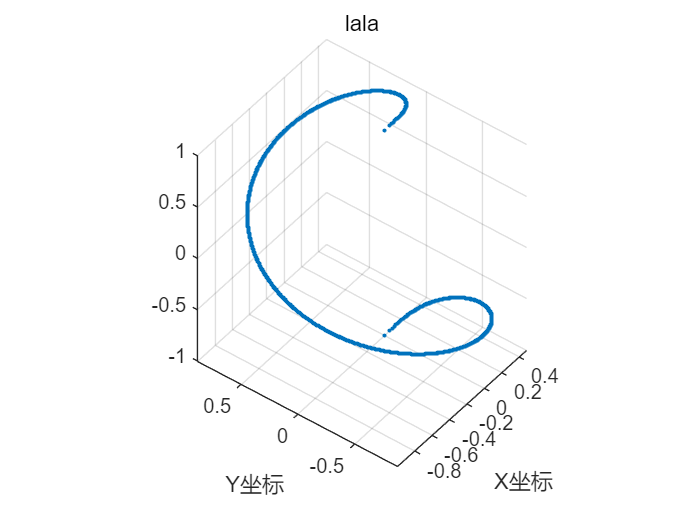


i = 0 : numPoints - 1;
dst = i / (numPoints - 1);
inclination = acos(1 - 2 * dst);
azimuth = 2 * pi * turnFraction * i;
x = sin(inclination) .* cos(azimuth);
y = sin(inclination) .* sin(azimuth);
z = cos(inclination);

figure; 
plot3(x, y, z, '.');

buffer = 0.1;
xLimit = xlim;
yLimit = ylim;
zLimit = zlim;

xlim([xLimit(1) - buffer, xLimit(2) + buffer]);
ylim([yLimit(1) - buffer, yLimit(2) + buffer]);
zlim([zLimit(1) - buffer, zLimit(2) + buffer]);

axis equal;

title('lala');
xlabel('X坐标');
ylabel('Y坐标');
grid on;